# Collect Statement and Function Coverage Metrics for MATLAB Source Code

When you run tests, you can collect and access code coverage information for your MATLAB® source code by adding an instance of the [`CodeCoveragePlugin`](docid:matlab_ref#bub472u) class to the test runner. In MATLAB, a plugin created using a [`CoverageResult`](docid:matlab_ref#mw_41f4d23d-989b-4dbf-a297-16f7b3fa40d6) or [`CoverageReport`](docid:matlab_ref#mw_24fca897-b57d-49f4-8fdc-797bb40033f6) format object provides information about statement and function coverage. For more information about statement and function coverage, see [Types of Code Coverage for MATLAB Source Code](docid:matlab_prog#mw_ba32526f-1995-4bb3-b9ab-bf8add8b08aa).

This example shows how to collect code coverage metrics and generate reports including statement and function coverage information for source code in a file. The file defines the `QuadraticPolynomial` class, which represents quadratic polynomials. The class constructor first validates that the coefficients of the polynomial are numeric values and then uses these values to initialize the class properties. The class includes the `solve` method to return the roots of the specified quadratic polynomial and the `plot` method to plot the polynomial around its axis of symmetry. To view the complete code for `QuadraticPolynomial`, see `QuadraticPolynomial` Class Definition.

## Collect and Analyze Code Coverage Information

In your current folder, save the `QuadraticPolynomial` class definition in a file named `QuadraticPolynomial.m`. Then, create the `QuadraticPolynomialTest1` test class in your current folder. The two `Test` methods in the class test the `solve` method against real and imaginary solutions.

To run tests and perform a code coverage analysis, first create a test runner with a plugin that provides programmatic access to the statement and function coverage information for source code in the file `QuadraticPolynomial.m`.

import matlab.unittest.plugins.CodeCoveragePlugin
import matlab.unittest.plugins.codecoverage.CoverageResult

runner = testrunner("textoutput");
format = CoverageResult;
plugin = CodeCoveragePlugin.forFile("QuadraticPolynomial.m",Producing=format);
addPlugin(runner,plugin)

Create a test suite from the `QuadraticPolynomialTest1` class and run the tests. The tests pass.

suite1 = testsuite("QuadraticPolynomialTest1");
run(runner,suite1);

After the test run, the `Result` property of the `CoverageResult` object holds the coverage result. Access the statement coverage summary from the coverage result. The returned vector indicates that the tests executed 8 out of the 17 statements in the file, resulting in 47% statement coverage. The statement coverage is low because the tests did not execute the code that throws an error and the code within the `plot` method.

result1 = format.Result;
statementSummary = coverageSummary(result1,"statement")

Access the function coverage summary. The summary indicates that the function coverage is 75% because the tests missed one of the four methods in the `QuadraticPolynomial` class (`plot`).

functionSummary = coverageSummary(result1,"function")

Use the additional output argument of the `coverageSummary` method to retrieve the execution count for each method.

[~,functionDescription] = coverageSummary(result1,"function")
disp([functionDescription.function.ExecutionCount])

## Generate Code Coverage Report

Now, generate an interactive HTML code coverage report from the coverage result. The report displays information about statement and function coverage and uses different colors to highlight the executed or missed statements and functions. 

generateHTMLReport(result1)

You can interact with the HTML code coverage report. For example, you can select a coverage type from the **Currently viewing** list to view detailed information about that coverage type, and you can control the highlighting for covered or missed executables. This figure shows the **Source Details** section for statement coverage, which displays all the statements that were covered or missed.

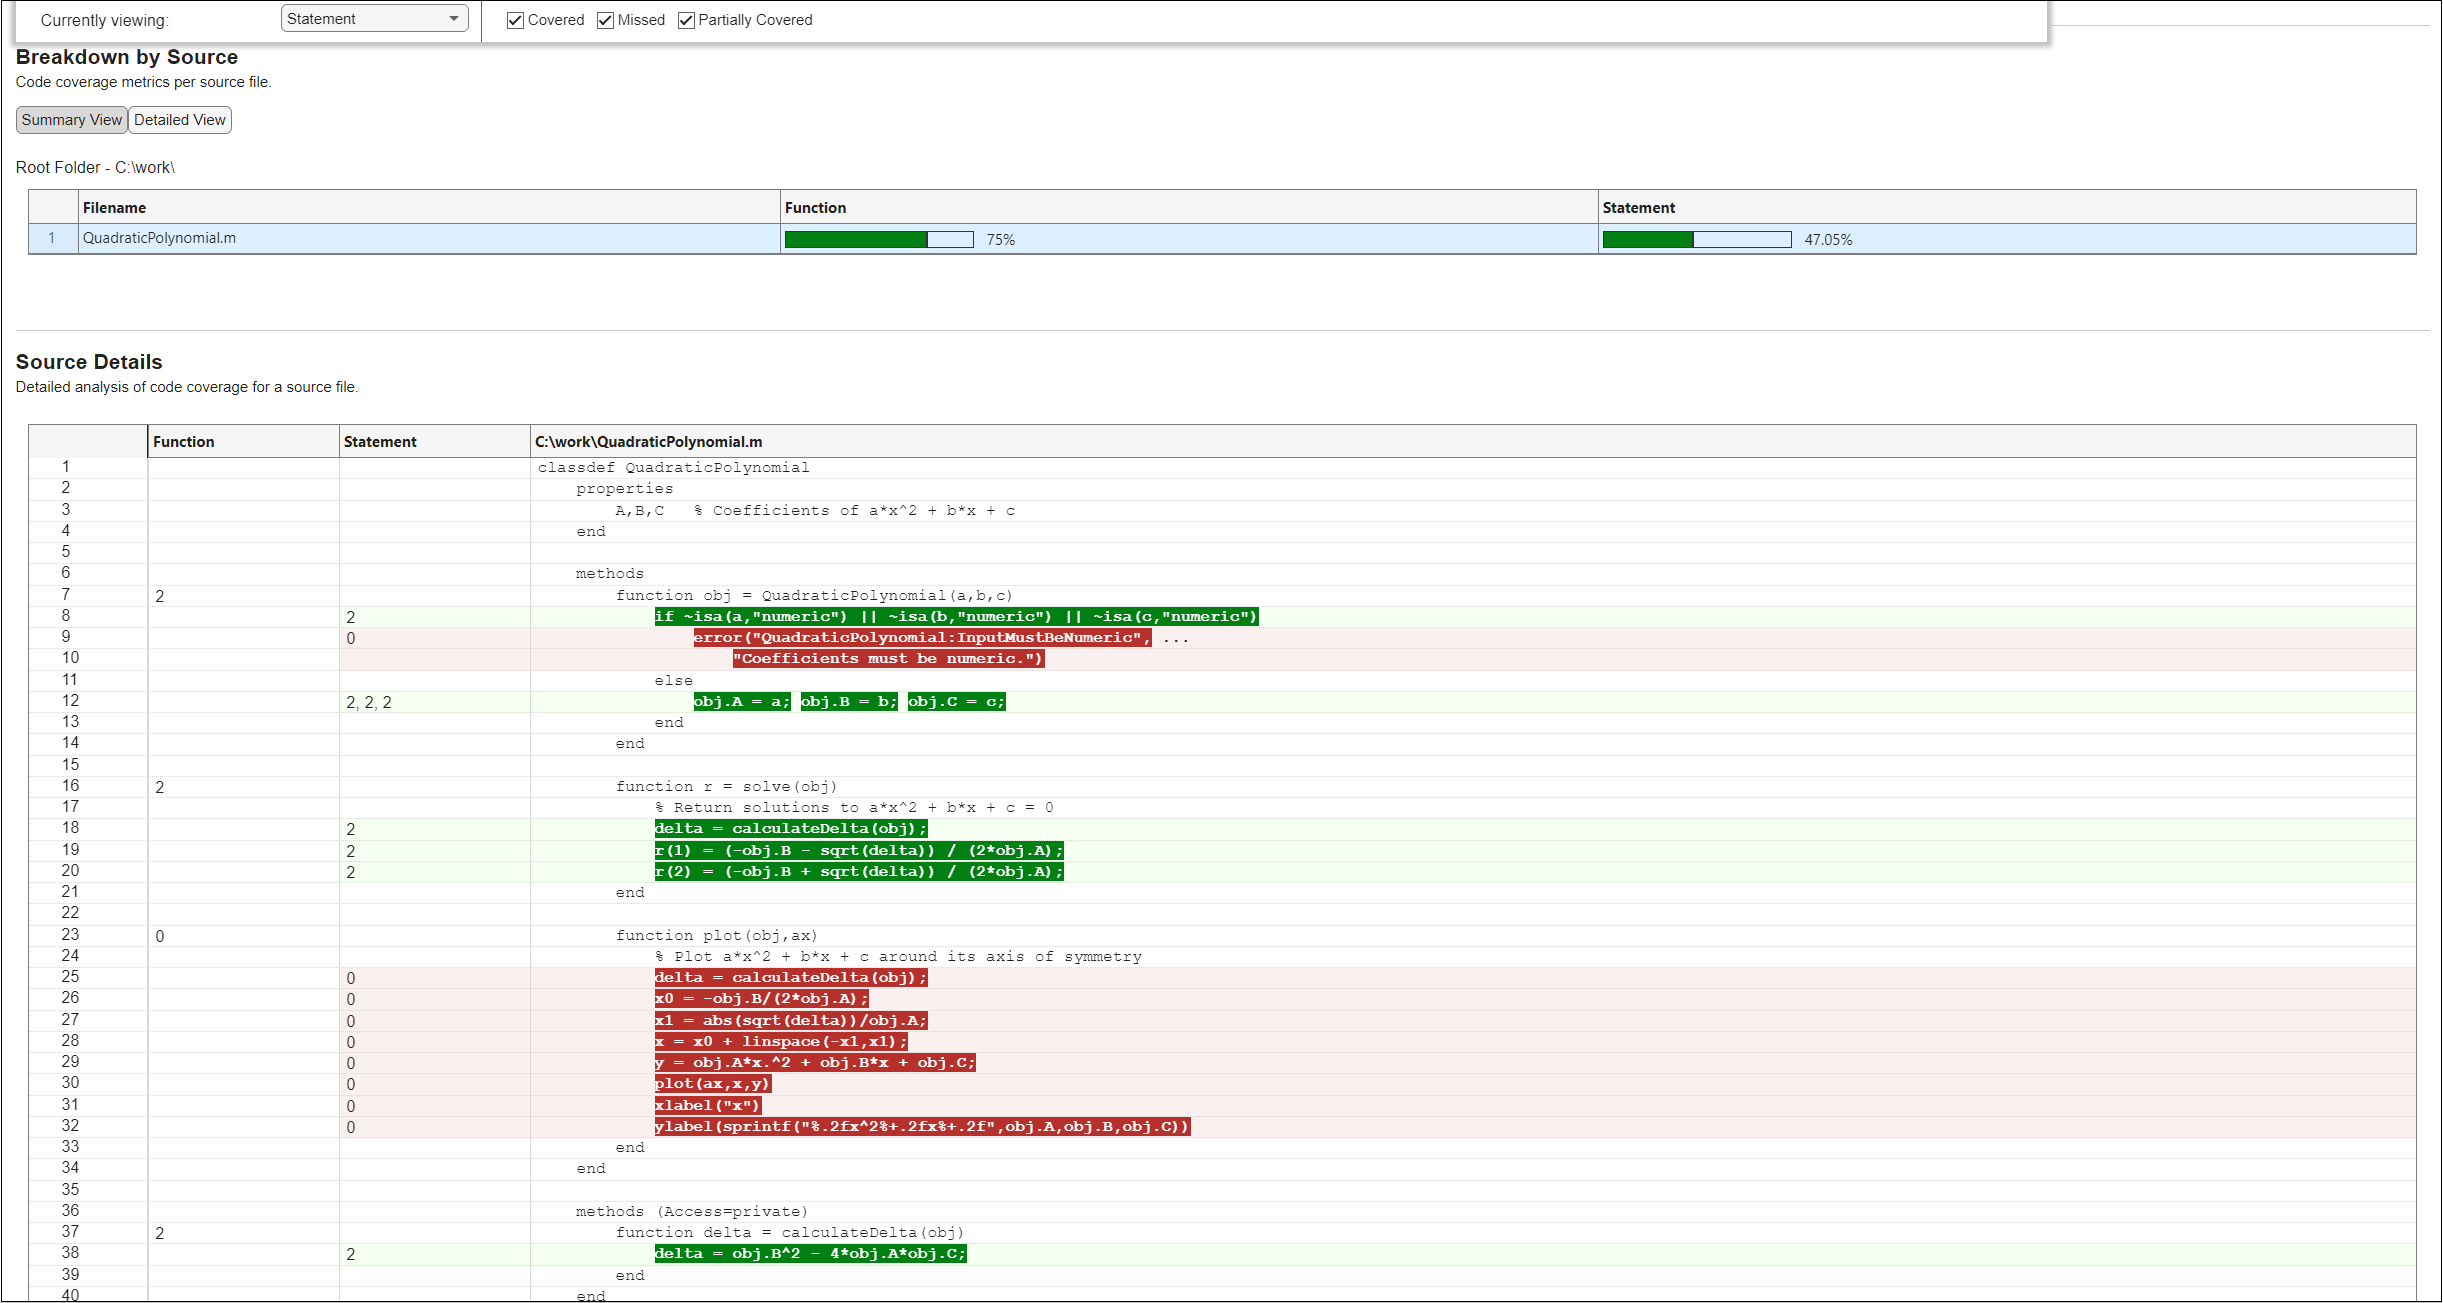

## Run Additional Tests to Improve Coverage

Create tests to execute the parts of the source code that were not executed by `suite1`. In your current folder, create another test class named `QuadraticPolynomialTest2`. One `Test` method in the class tests against nonnumeric inputs, and the other `Test` method tests properties of a plotted polynomial.

Create a test suite from the `QuadraticPolynomialTest2` class and run the tests. The tests pass.

suite2 = testsuite("QuadraticPolynomialTest2");
run(runner,suite2);

In this example, you ran different test suites to qualify the same source code. To report on the total aggregated coverage for these test runs, generate an interactive HTML report from the union of the coverage results corresponding to the test runs. The report shows that the two test suites combined fully exercised the statements and functions in the source code.

result2 = format.Result;
generateHTMLReport(result1 + result2)

## `QuadraticPolynomial` Class Definition

This code provides the complete contents of the `QuadraticPolynomial` class.

*Copyright 2022 The MathWorks, Inc.*